# Manipulate the Equations Of Motion

Plug in Numerical Parameters and Linearize the System About the Unstable Equilibrium Point

cd 'F:\Sourcetree Repos\Matlab Personal\Ball Plate Thesis'
addpath('Kinematics')
addpath('Kinetics')

sympref('FloatingPoint',true);

supressed_print= evalc('run Ball_Plate_Kinetics_Newton_Euler.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

## Best Current Estimates of Numerical System Parameters

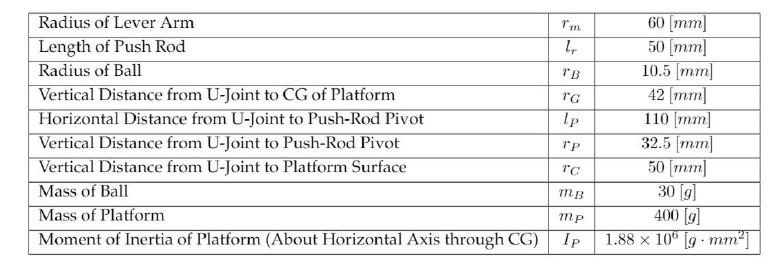

rB = .0105; %[m]
rG = .042; %[m]
rC = .050; %[m]
mB = .030; %[kg]
mP = .400; %[kg]
IP = 1.88e6*(1/1000)*(1/1000)^2; %[kg*m^2]
%IPz = 0;%For some reason

Num_Params = [rB  rC+rB mB mP IP ];
Sym_Params = [r_b z_b m_b m_p I_p__xx ];

Substitute Known Numerical Parameters Into Symbolic EOMs

NumEOMs = simplify(subs(SolvedEOMS, Sym_Params, Num_Params))